clc
clear all

scale = 0.948/0.7 % 0.4626

scale = 1.3543

ff = 5; % 8.0840
alpha = deg2rad(55/2); %input in deg 79.8571
beta = alpha;  %input in deg

R = 11.3284%8.354*(scale) %mm

R = 11.3284

a = 18.3857%12.531*(scale) %found by reducing or increasing such that gammamax - gammamin = alpha + beta

a = 18.3857

b = 19.3757%*(scale)

b = 19.3757

H = 64.8591%45.86*(scale)

H = 64.8591

C = 8.4857%7.31*(scale)

C = 8.4857


x = 4;
i = 0;

a1 = 4.384;
b1 = 28.61;
c1 = 0.3897;
a2 = 11.13;
b2 = 1.114;
c2 = -0.02109;
a3 = 0.6049;
b3 = 69.68;
c3 = 0.5609;

% a1 = 0.9449;
% b1 = 50.42;
% c1 = -0.08977;
% a2 = 0.9526;
% b2 = 1.74;
% c2 = 2.857;
% a3 = 0.1678;
% b3 = 103.3;
% c3 = 0.629;
% a1*sin(b1*x+c1) + a2*sin(b2*x+c2) + a3*sin(b3*x+c3)

for theta = 0:0.1:(2*pi)
    i = i+1;
    A = H - R*((sqrt((x^2)-(sin(theta))^2)) + cos(theta));
    epsilon = atan(A/C);
    zeta(i) = epsilon;
    f = acos(((A^2) + (C^2) - (a^2) - (b^2))/(-2*a*b));
    g = b*sin(f)/(sqrt((C^2) + A^2));
    %gamma = alpha - ((atan((H -R*((sqrt(x^2 - (sin(theta))^2) + cos(theta))))/C)) - asin(b*sin(acos((H -R*((sqrt(x^2 - (sin(theta))^2) + cos(theta))) + (C^2) - (a^2) - (b^2)))/(-2*a*b))/(sqrt((C^2)+ (H -R*((sqrt(x^2 - (sin(theta))^2) + cos(theta)))^2)))))
    gamma(i) = alpha - (zeta(i) - g);
    t(i) = theta/(2*pi*ff);
    L(i) = a1*sin(b1*t(i) + c1) + a2*sin(b2*t(i) + c2) + a3*sin(b3*t(i) + c3);
    m = 2*(sqrt((x^2) - (sin(theta))^2));
    n(i) = b*(sqrt(1 - ((C - a*cos(alpha - gamma(i)))/b)^2));
    o(i) = a*(C - a*cos(alpha - gamma(i)))*sin(alpha - gamma(i));
    e = R*(((sin(2*theta))/m) + sin(theta));
    w(i) = a*cos(alpha - gamma(i));
    gammadot(i) = 2*pi*ff*e/((o(i)/n(i)) - w(i));
    tau(i) = 0.47*L(i)*990*gammadot(i)/(2*(2*pi*ff));
end

gammamax = rad2deg(max(gamma))

gammamax = 39.1102

gammamin = rad2deg(min(gamma))

gammamin = -15.9343

mingammarad = min(gamma)

mingammarad = -0.2781


angle = (gammamax - gammamin)

angle = 55.0446


stnumber =(ff*0.482430503*sin((deg2rad(angle/2))))/8

stnumber = 0.1393

zetamax = max(zeta);
zetamin = min(zeta);
zetamax - zetamin

ans = 0.5332

disp("zeta min should be 40 or more")

zeta min should be 40 or more


rad2deg(zetamin)

ans = 44.0787

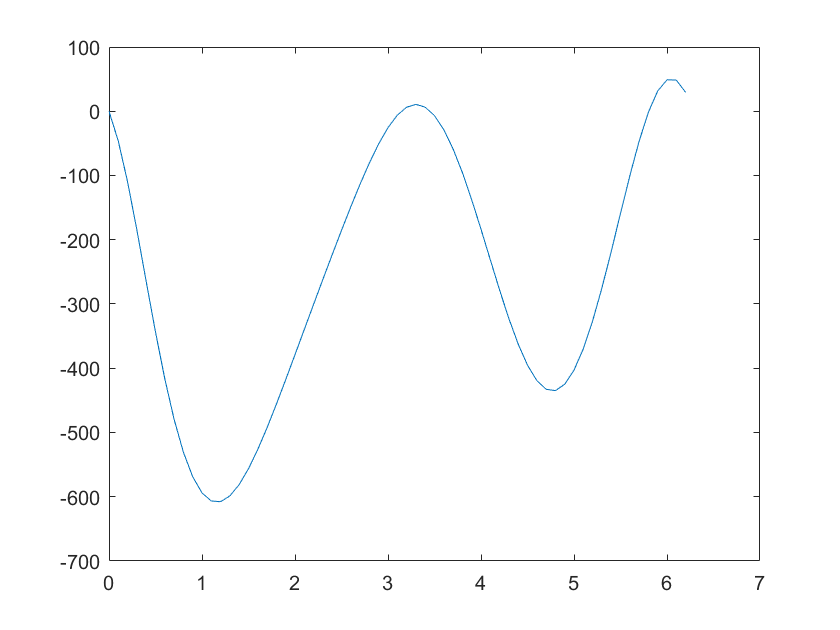

plot(0:0.1:(2*pi),tau);

p = (2*pi*ff)*(tau)/1000

p =          0   -1.4590   -3.4575   -5.8126   -8.3228  -10.7983  -13.0829  -15.0636  -16.6708  -17.8715  -18.6615  -19.0574  -19.0915  -18.8063  -18.2506  -17.4760  -16.5328  -15.4675  -14.3199  -13.1226  -11.8997  -10.6679   -9.4381   -8.2170   -7.0098   -5.8232   -4.6676   -3.5598   -2.5238   -1.5915   -0.8004   -0.1908    0.1988    0.3363    0.2008   -0.2151   -0.9040   -1.8439   -3.0000   -4.3261   -5.7672   -7.2615   -8.7421  -10.1401  -11.3863  -12.4152  -13.1674  -13.5943  -13.6607  -13.3486


plot(0:0.1:(2*pi),abs(p));
p_max = (2*pi*ff)*max(abs(tau))/1000   

p_max = 19.0915

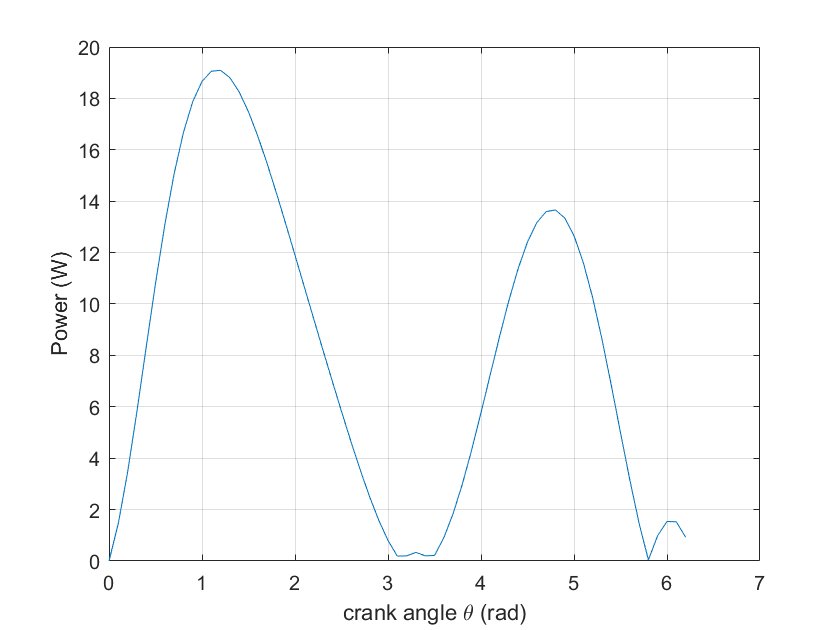

%title('Instantaneous Power for Flapping Mechanism')
xlabel('crank angle \theta (rad)')
ylabel('Power (W)')
grid on 


max(abs(tau))

ans = 607.7014

p_abs = abs(p)

p_abs =          0    1.4590    3.4575    5.8126    8.3228   10.7983   13.0829   15.0636   16.6708   17.8715   18.6615   19.0574   19.0915   18.8063   18.2506   17.4760   16.5328   15.4675   14.3199   13.1226   11.8997   10.6679    9.4381    8.2170    7.0098    5.8232    4.6676    3.5598    2.5238    1.5915    0.8004    0.1908    0.1988    0.3363    0.2008    0.2151    0.9040    1.8439    3.0000    4.3261    5.7672    7.2615    8.7421   10.1401   11.3863   12.4152   13.1674   13.5943   13.6607   13.3486


mean(p_abs)

ans = 8.1730